%Getting raw data from the website
url='http://api.covid19india.org/csv/latest/state_wise_daily.csv';
raw=webread(url);

2

%Creating confirmed and recovered arrays which will contain the infected
%and recovered cumulative data respectively
j=1;
%Initialising the AP column with the first row containing initial confirmed
%case
i=1;
%Initialising the AP column with second-row containing initial recovered
%case
k=2;
confirmed (j) =0;
recovered (j) =0;
while (i<length(raw.AP))
    confirmed (j+1) =confirmed(j)+raw.AP(i);
    recovered (j+1) =recovered(j)+raw.AP(k);
    j=j+1;
    i=i+3;
    k=k+3;
end

3

%% Finding constants beta and Gamma from the data
 
%N is the assumed exposed population in Andhra Pradesh
N=50000;
%"d" is the unique dates frm the raw data
d=unique(raw.Date);
%Creating infected and recovered arrays from "confirmed" and "recovered"
%arrays respectively
infected=confirmed(2:end)' ;
recovered=recovered(2:end)';
%Since N=suspectable+infected+recovered
susceptible=N-infected-recovered;
%The step size is one day
dt=1;
 
for i=1:(length(susceptible)-1)
    b(i)=(susceptible(i)-susceptible(i+1))/(susceptible(i).*infected(i)*dt);
end
 
for i=1:(length(susceptible)-1)
    g(i) =(recovered(i+1)-recovered(i))/( infected(i)*dt ) ;
end
 
%Take the final value of b and g arrays as beta and gamma respectively
gamma=g(end);
beta=b(end);

4

%%
%Using the calculated "beta" and "gamma" we will generate future
%Susceptible, Infected and Recovered using SIR Model
 
%Initialising Sucseptable, Infected, and Recovered arrays with last date
%values in the raw data respectively
susc=[susceptible(end) inf];
infec=[infected(end) inf];
rec=[recovered(end) inf];
%The first date of prediction will be equal to last date of actual data
d1=d(end);
%Specify the last date of prediction
d2=datetime(0021,12,30);
d_interval=d1:d2;
 
%Finding Susceptible, Infected, and Recovered array elements starting from
%today to the specified date in "d2" variable using SIR Model
for i=1:length(d_interval)-1
    
    susc(i+1)=(susc(i)-((beta)*susc(i).*infec(i)*dt));
    infec(i+1)=(infec(i) +(((beta)*susc(i).*infec(i))-...
        ((gamma).*infec(i))) *dt);
    rec(i+1) =(rec(i) +(((gamma).*infec(i))*dt));
    
end
%Rounding the values
calculated_susceptible=round(susc');
calculated_infected=round(infec');
calculated_recovered=round(rec');

5

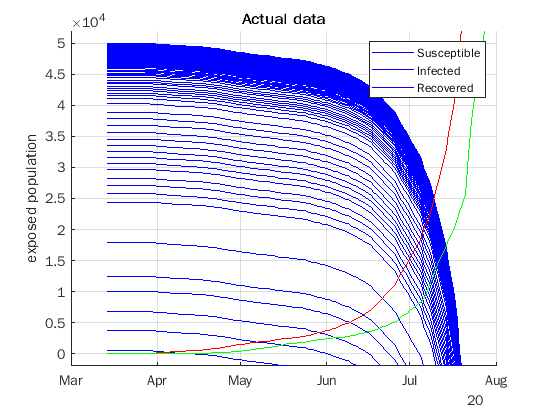

%% Plot
%Plotting actual data
figure(1);
hold on;
plot(d,susceptible,'b');
plot(d,infected,'r');
plot(d,recovered,'g');
ylim([-2000 52000]);
title('Actual data');
ylabel('exposed population');
legend('Susceptible','Infected','Recovered');
grid on;

6

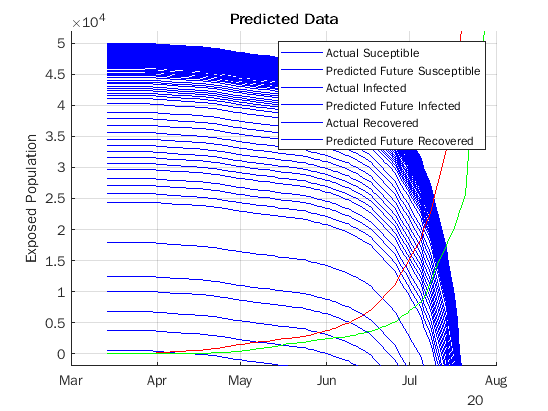

%Plotting the predicted data along with the actual data
figure(2);
hold on;
plot(d(:),susceptible,'b',d_interval,calculated_susceptible,'--b');
plot(d(:),infected,'r',d_interval,calculated_infected,'--r');
plot(d(:),recovered,'g',d_interval,calculated_recovered,'--g');
ylim([-2000 52000]);
title('Predicted Data');
ylabel('Exposed Population');
legend('Actual Suceptible','Predicted Future Susceptible',...
    'Actual Infected','Predicted Future Infected','Actual Recovered',...
    'Predicted Future Recovered');
grid on;

gamma

gamma = 2.0050e-04

beta

beta = -9.1578e-11

7

function SIR
% b = 0.005 % probability of contracting the disease
b = beta
N = 500000
% g = 0.15 % recovery rate
g = gamma
    function F = func(t, x)    %set up the function to be solved in a seperate function environment
        F = zeros(2,1)
F(1) = - b*x(2)*x(1)/N % Susceptible differential equation
F(2) = b*x(2)*x(1)/N - g*x(2) % Infectious differential equation
F(3) = g*x(2)% Recovered differential equation
end 
%x0 = [495; 5; 0]; % Initial 495 Susceptible and 5 Infectious
%t = linspace(0, 30, 600); % 30-week duration (600 data points)
options = odeset('Refine', 10, 'RelTol', 1e-4)
[t,y] = ode45(@func, [0 30], [495 5 0], options)
plot(t, y)
legend ('Susceptible', 'Infectious', 'Recovered')
end